# Clear workspace , and command window, close all figures already open.

close all, clear all, clc;

## Read the RGB Image and create figure

image = imread('BIM472_HW1.jpg');
figure(1);

## A - Convert RGB image to Grayscale

imageGray =  rgb2gray(image);
imwrite(imageGray, 'grayImgBIM472_01.png');
subplot(3,2,2), imshow(imageGray);
title('Grayscale Image');


The problem can be solved by two different approach:

- built-in incomplement function.

- exploiting Matlab data class features.

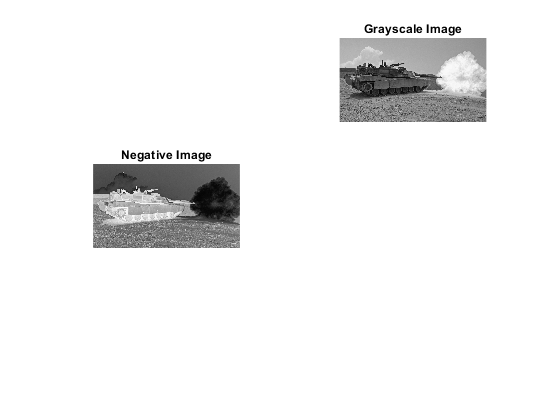

imageNegative = 255-imageGray;
imwrite(imageNegative, 'negativeBIM472_01.png');
subplot(3,2,3), imshow(imageNegative);
title('Negative Image');

## B - Flip the Image

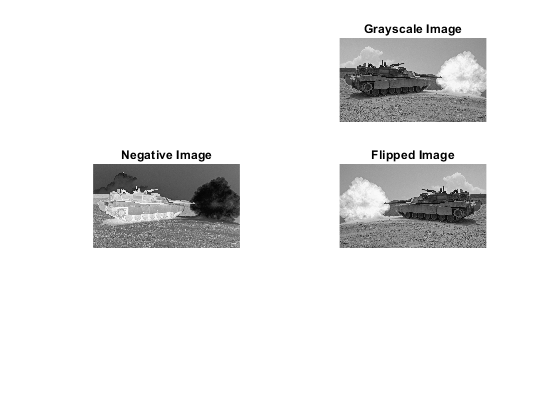

imageFlipped = fliplr(imageGray); 
imwrite(imageFlipped, 'mirrorImgBIM472_01.png');
subplot(3,2,4), imshow(imageFlipped);
title('Flipped Image');

## C - Swap channels

The problem can be solved by two different approach:

- built-in permute function.

- traditional channel swapping.

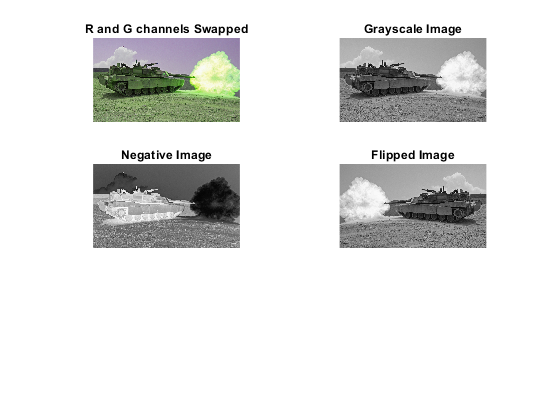

R = image(:,:,1);
G = image(:,:,2);
B = image(:,:,3);
imageSwapped(:,:,1) = G;
imageSwapped(:,:,2) = R;
imageSwapped(:,:,3) = B;
imwrite(imageSwapped, 'swapImgBIM472_01.png');
subplot(3,2,1), imshow(imageSwapped);
title('R and G channels Swapped');

## D - Average Gray Image with Flipped

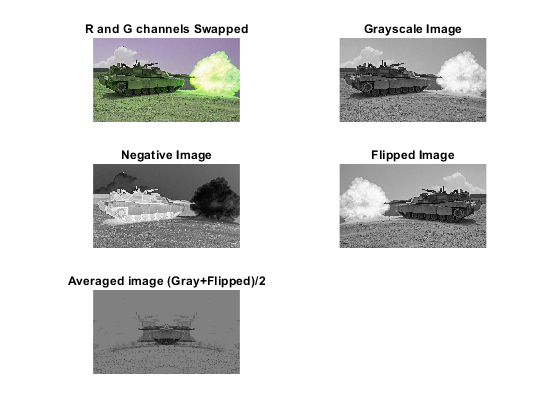

imageAverage = (imageGray+imageFlipped)/2;
imwrite(imageAverage, 'avgImgBIM472_01.png');
subplot(3,2,5), imshow(imageAverage);
title('Averaged image (Gray+Flipped)/2');

## E - Add Noise

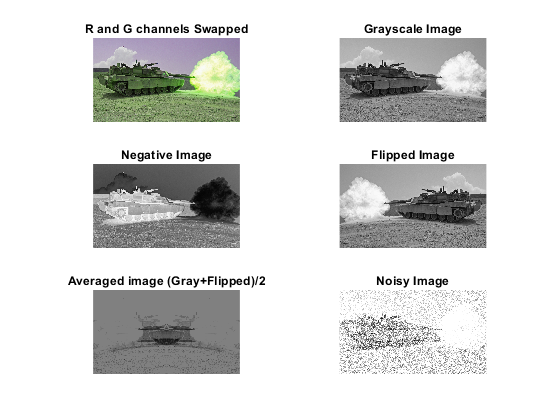

N = uint8(randi(255, size(imageGray)));
save('noise.mat', 'N');
imageClipped = imageGray+N;
imwrite(imageClipped, 'addNoiseImgBIM472_01.png');
subplot(3,2,6), imshow(imageClipped);
title('Noisy Image');